## Logistic Map: 


$$x_{\mathrm{n+1}} = rx_{\mathrm{n}}\left(1 - x_{\mathrm{n}}\right)$$


number_iterations = 1000;
number_r_values = 1000;
number_above_which_to_plot = 300; % gets rid of transients in evolution of x.
number_to_plot = -(number_above_which_to_plot - number_iterations);
r_start = 3.847; % for these values, zoom in on one branch to see the repeating orbit diagram
%r_start = 3.3;
r_stop = 3.867;
% r_stop = 4;
r_step = (r_stop - r_start)/number_r_values;
x_0 = .3; % initial condition
iteration_results = zeros(number_r_values, number_iterations);
r_values = zeros(number_r_values, 1);

iteration_results(:, 1) = x_0;
r = r_start;
for r_iteration = 1:number_r_values
    for x_iteration = 2: number_iterations
       iteration_results(r_iteration, x_iteration) = r*iteration_results(r_iteration, x_iteration - 1)* ...
           (1- iteration_results(r_iteration, x_iteration - 1));
    end
    r_values(r_iteration) = r;
    r = r + r_step;
end
r_values_array = repmat(r_values, [1, number_to_plot]);

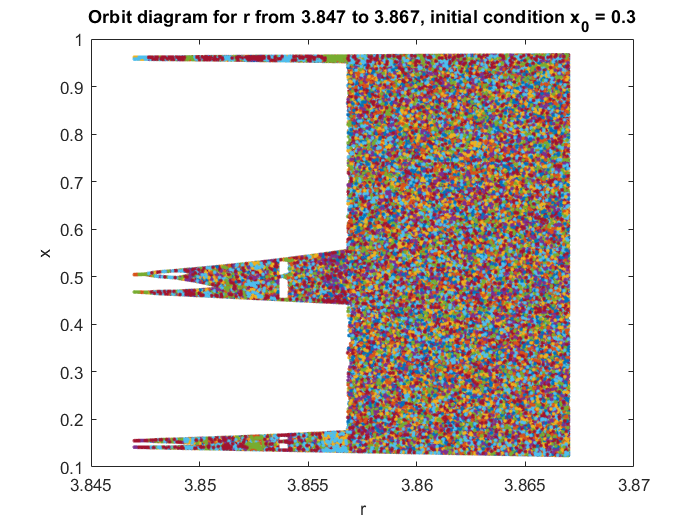

figure
plot(r_values_array, iteration_results(:, end - number_to_plot + 1:end),'.')
title(['Orbit diagram for r from ' num2str(r_start) ' to ' num2str(r_stop) ', initial condition x_0 = ' ...
    num2str(x_0)])
xlabel('r')
ylabel('x')